# Week 10: RRT

*Author: Keith Chester*

*E-mail: kchester@wpi.edu*

## Introduction

In this assignment, we are exploring the application of the Rapidly-exploring Randomized Tree (RRT) algorithm and its application to robots. To this end, we will be applying the algorithm to a grid-map generated from a floor plan schematic, to emulate a realistic navigation use-case.

## Methods

RRT is a space-filling tree algorithm, similar to random forests, designed to maximize exploration of a given domain. This is ideal for the application of search algorithms for navigation.

We first need to create the map of our area. If we were working directly with robotic arms, we could use the configuration maps that we generated in last week's assignment to create a set of configurations to get between a current and desired arm configurations, while avoiding obstacles. Alternatively, for a mobile robot, we could load in a map of the room or environment that we are operating in. For this assignment, we chose an image of a floor plan schematic (simplified for our purposes, by keeping only the walls of the schematic).

For our example, we will be taking a floor plan schematic png file and converting it to a binary occupancy map. This process involves taking the image in question, and converting it to black and white. This takes the normally 4 channel png (red, green, blue, and alpha, or RGBA) and convers it to a singular value for its color value. This singular averaged color value will be used to determine the intensity of data in this spot.

We then copy only data from pixels within the image that meet a certain trheshold value, to create a further distinction between "filled" and "empty" pixels. From here, we can create a binary occupancy map.

Once we have the map, we define a series of variables for the sake of our RRT planning. First, we create a state space for the $\textrm{SE2}$ set. This is a collection of points within our state that our planner will be saving its route in, consisting of a given x, y, and $\theta$. From this we create a validator occupancy map, which, for a given 2D state space, ensures that a given configuration or change is valid or not. Here on the validator we define world limits as well, preventing the planner from seeking outside the given state space - as well as set the limits to $\theta$.

Once we have these defined, we create an RRT planner, which accepts our given state space and our validator map.  One noteworthy setting we work with is the *MaxConnectionDistance*. This setting configures that maximum distance that the tree planner can "jump" when generating nodes. It must be configured to deal with the different size images passed to the planner, or the planner will not be able to find a solution.

Finally, we set the destination and goal coordinates. We take the planner's solutions and explored routes and plot them over the image to demonstrate its exploration and path solution.

## Results

First, we load the image from the local folder. *floorplan.png* is a file that is expected to be within the same active folder as the live script is operating out of.

Once read, we convert the imageto a binary occupancy map by averaging the color channels via a black and white filter and then thresholding those values.

I = imread('floorplan.png');
grayimage = rgb2gray(I);
bwimage = grayimage > 1;

grid = binaryOccupancyMap(bwimage);

show(grid)

Here we allow you to set a goal and ask the RRT path planner to find a path to it. It will reload the image as well, as the state space is re-used between runs unless you reinitialize the planner and state space.

Set a start and goal to an X/Y position within the floorplan, and a path should be found if one exists:

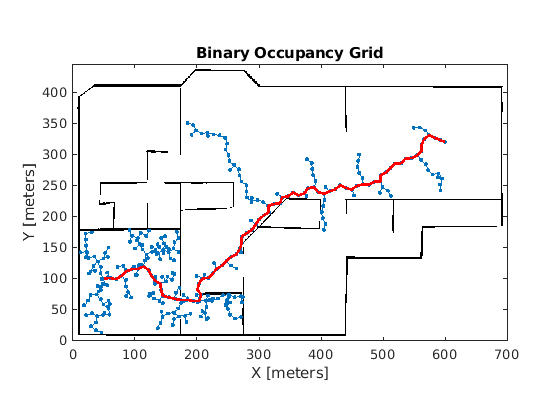

start_x = 50;
start_y = 100;
start = [start_x, start_y, 0];

goal_x = 600;
goal_y = 320;
goal = [goal_x, goal_y, 0];

 

ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);
sv.Map = grid;
sv.ValidationDistance = 0.01;
ss.StateBounds = [grid.XWorldLimits;grid.YWorldLimits; [-pi pi]];

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 10;

rng(100,'twister'); % for repeatable result
[pthObj,solnInfo] = plan(planner,start,goal);

hold on
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-'); % tree expansion
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2) % draw path
hold off

The expected output of this will be like the figure below. If the coordinates chosen for the goal/start are not within the room, an error might be thrown or a occupancy grid filled with nodes but no path will be present.

*Figure 1: Example Mapped Path*

Here we can graph the X, Y, and $\theta$ for the path as planned. Once we graph that, we can also graph the Deltas of the X, Y, and $\theta$for the given path planned.

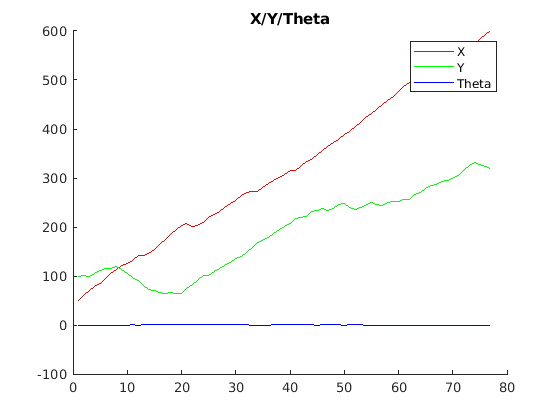

figure;
title("X/Y/Theta")
hold on;
plot(pthObj.States(:,1), "r");
plot(pthObj.States(:, 2), "g");
plot(pthObj.States(:, 3), "b");
legend("X", "Y", "Theta")
hold off;

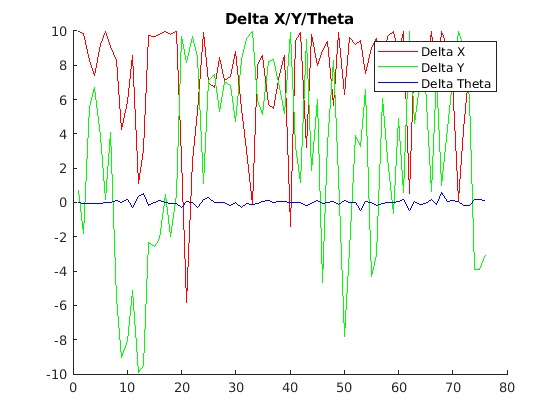


figure;
title("Delta X/Y/Theta")
hold on;
plot(diff(pthObj.States(:,1)), "r");
plot(diff(pthObj.States(:, 2)), "g");
plot(diff(pthObj.States(:, 3)), "b");
legend("Delta X", "Delta Y", "Delta Theta")
hold off;

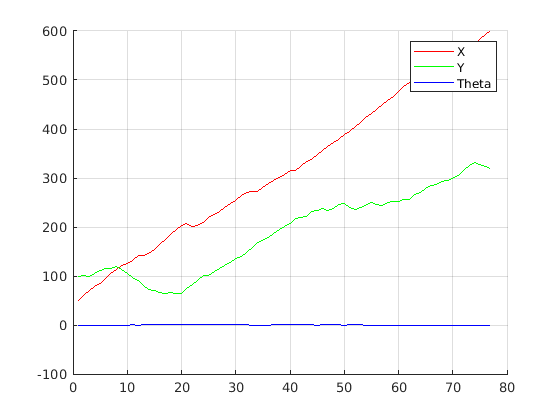

*Figure 2: Example X, Y, and *$\theta$*values for the planned path*

*Figure 3: Example Delta X, Y, and *$\theta$ for the planned path

## Discussion

In this assignment, we explored the use of the RRT planner as a search algorithm to generate panned paths between an initial and desired position. For this demonstration we applied it to a floorplan design to correlate it to the common task of planning a path for a robot in cartesian space. It is also applicable, however, to the task and configuration spaces that we have recently been working in to plan motions for robotic arms.

Other planning algorithms, such as RRT* (an optimized verson of RRT which finds the optimal path), PRM (Probablistic roadmap, which uses custom sampling to build a graph of paths while avoiding collisions with obstacles) and A* (a depth first search with an ordered queue of neighbors based on a heuristic, such as distance from the goal) should be the focus of further investigation.